# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;
storeFigures = true; % set true if you want to save plots

## Problem 1:

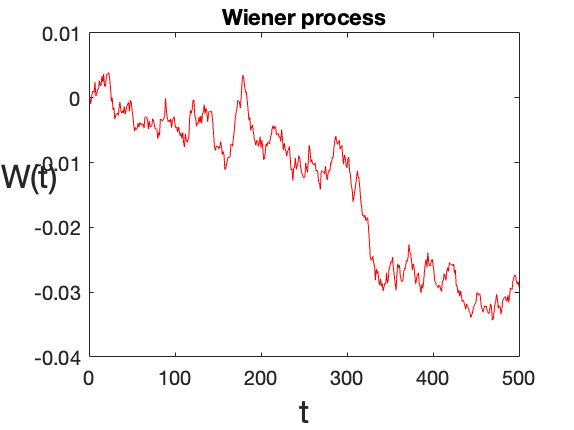

% Y(s) = 1/(1+s*tau)^2 *(U(s)+D(s))
% Find continusous-time stochastic state space model
% Create disturbance as a Wiener process
% Intensity of disturbance Q = 0.001

Qc  = [0.001 0; 0 0.001];
Rc  = 0.0001;
n_seconds = 500;

% Solution
% Continuous-time system

% Wiener Process 
N = 500; 
dt = n_seconds/N;

dW = zeros(1,N);                
W = zeros(1,N);                 
dW(1) = 0.001*sqrt(dt)*randn();    
W(1) = dW(1);                  
for j = 2:N
    dW(j)= 0.001*sqrt(dt)*randn();
    W(j) = W(j-1) + dW(j);
end
figure(1);
plot([0:dt:n_seconds],[0,W],'r-')     
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");

% mean and variance
MeanWiener = mean(W)

MeanWiener = -0.0139

VarianceWiener = var(W)

VarianceWiener = 1.3609e-04

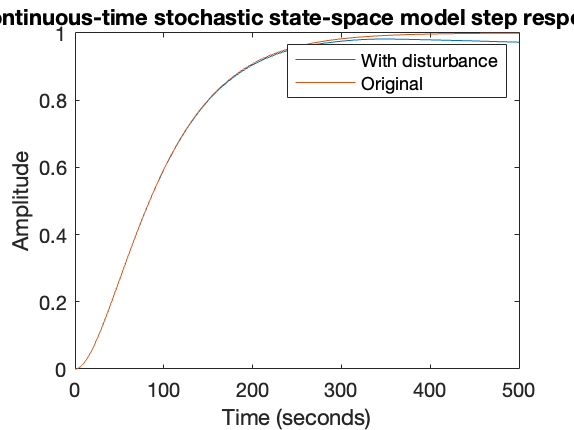



tau = 50; % 50 seconds
sys = tf(1,[tau^2 2*tau 1]);
step_input = ones(1,N+1);
disturbance = [0,W];
response = lsim(sys,step_input+disturbance,[0:dt:n_seconds]);
response_original = lsim(sys,step_input,[0:dt:n_seconds]);

figure(2);
plot([0:dt:n_seconds],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Continuous-time stochastic state-space model step response");
hold on
plot([0:dt:n_seconds],response_original);
legend("With disturbance","Original");

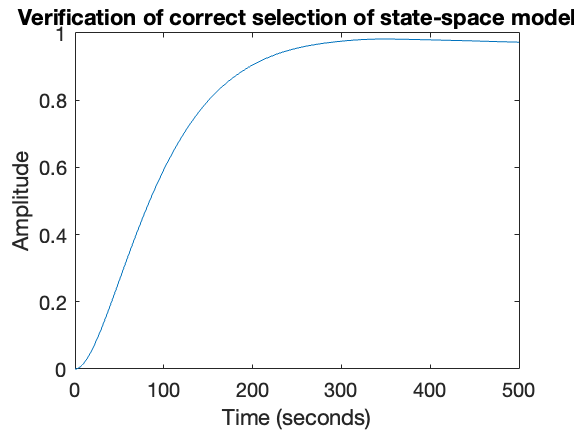

legend show
fix_ylim = ylim;

% . 
% x = Ax + Bu + Gw      {State equation}
% y = Cx + Du +  v      {Measurements}

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
B = [B G];
D = [D 0];
sys = ss(A,B,C,D);
step_input = ones(1,N+1);
disturbance = [0,W];
%% verification of stochastic state space model derivation
response = lsim(sys,[step_input;disturbance],[0:dt:n_seconds]);
figure(3);
plot([0:dt:n_seconds],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Verification of correct selection of state-space model");

## Problem 2:

% Find discrete-time model
% Find Kalman filter
% Ts = 20s
% Evaluate predicted and filtered values
Ts = 20*dt;
dsys = c2d(sys,Ts,'tustin');
% funQ = @(x) expm(A*x)*Qc*expm(A'*x);
% funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';
% Qn = integral(funQ,0,Ts,'ArrayValued', true);
% Rn = integral(funR,0,Ts,'ArrayValued', true);
% Rn = Rn + Rc;
S = [0.001; 0.001];
Px = 10*eye(2);
Qn = A*Px*A'+ Qc;
Sn = A*Px*C'+ S;
Rn = C*Px*C'+ Rc;
[kest,L,P,M,Z] = kalman(dsys,Qn,Rn,Sn);
P % minimal prediction co-variance  P(t|t-1)

P = 	1.0e+03 *

    0.6183    1.2043
    1.2043    5.5307


Z % minimal filtering co-variance   P(t|t)

Z = 	1.0e+03 *

    0.3107    0.4309
    0.4309    3.5862


## Problem 3:

% Find Kalman Filter models
% Use asynchronous sampling with controller computation time
% Tc = 10/1/0.1/s
% Compare properties of noise models
% Evaluate P (predicted value)

Ts = 20*dt;
Tcs = [10 1 0.1]*dt;
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    funB = @(x) expm(A*x);
    funD = @(x) expm(A*x);
    funQ = @(x) expm(A*x)*Qc*expm(A'*x);
    funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
    funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';

    Aasync = expm(A*Ts);
    Casync = C*expm(A*etta*Ts);
    Basync = integral(funB,0,Ts,'ArrayValued', true);
    Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
    Q = integral(funQ,0,Ts,'ArrayValued', true);
    S = integral(funS,0,etta*Ts,'ArrayValued', true);
    R = integral(funR,0,etta*Ts,'ArrayValued', true);
    Basync = Basync*B;
    Dasync = C*Dasync*B;
    R = Rc + R;

    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Tcs(i)),Q,R,S);
    P
    Z
end

Tc


    10



P = 	1.0e+04 *

    0.0250    0.1971
    0.1971    1.6343


Z = 	1.0e+03 *

    0.0171    0.0891
    0.0891    1.1309


Tc


     1



P =    41.8238   85.9226
   85.9226  740.0424


Z =    33.0200   60.3392
   60.3392  665.6981


Tc


    0.1000



P =    27.0894   48.5662
   48.5662  619.9598


Z =    23.5563   37.8957
   37.8957  587.7330


## Problem 4:

% Show impact of neglecting S in case of asynchronous sampling
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;

    funB = @(x) expm(A*x);
    funD = @(x) expm(A*x);
    funQ = @(x) expm(A*x)*Qc*expm(A'*x);
    funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
    funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';

    Aasync = expm(A*Ts);
    Casync = C*expm(A*etta*Ts);
    Basync = integral(funB,0,Ts,'ArrayValued', true);
    Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
    Q = integral(funQ,0,Ts,'ArrayValued', true);
    S = integral(funS,0,etta*Ts,'ArrayValued', true);
    R = integral(funR,0,etta*Ts,'ArrayValued', true);
    Basync = Basync*B;
    Dasync = C*Dasync*B;
    R = Rc + R;

    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    disp("With S")
    P
    Z
    disp("Value of determinant with S")
    disp(det(P))
    disp("With S=0")
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R);
    P
    Z
    disp("Value of determinant without S")
    det(P)
end

Tc


    10



With S


P = 	1.0e+04 *

    0.0250    0.1971
    0.1971    1.6343


Z = 	1.0e+03 *

    0.0171    0.0891
    0.0891    1.1309


Value of determinant with S


   1.9965e+05



With S=0


P = 	1.0e+04 *

    0.0250    0.1977
    0.1977    1.6424


Z = 	1.0e+03 *

    0.0170    0.0885
    0.0885    1.1265


Value of determinant without S


ans = 1.9974e+05

Tc


     1



With S


P =    41.8238   85.9226
   85.9226  740.0424


Z =    33.0200   60.3392
   60.3392  665.6981


Value of determinant with S


   2.3569e+04



With S=0


P =    43.5880   90.9456
   90.9456  754.6480


Z =    33.9951   63.0886
   63.0886  673.7543


Value of determinant without S


ans = 2.4623e+04

Tc


    0.1000



With S


P =    27.0894   48.5662
   48.5662  619.9598


Z =    23.5563   37.8957
   37.8957  587.7330


Value of determinant with S


   1.4436e+04



With S=0


P =    28.2612   51.2440
   51.2440  628.0586


Z =    24.3899   39.6566
   39.6566  593.3755


Value of determinant without S


ans = 1.5124e+04

%% Conclusion: inclusion of S decreases the values of covariances

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with decorrelated noise
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;

funB = @(x) expm(A*x);
funD = @(x) expm(A*x);
funQ = @(x) expm(A*x)*Qc*expm(A'*x);
funS = @(x) expm(A*x)*Qc*expm(A'*x)*C';
funR = @(x) C*expm(A*x)*Qc*expm(A'*x)*C';

Aasync = expm(A*Ts);
Casync = C*expm(A*etta*Ts);
Basync = integral(funB,0,Ts,'ArrayValued', true);
Dasync = integral(funD,0,etta*Ts,'ArrayValued', true);
Q = integral(funQ,0,Ts,'ArrayValued', true);
S = integral(funS,0,etta*Ts,'ArrayValued', true);
R = integral(funR,0,etta*Ts,'ArrayValued', true);
Basync = Basync*B;
Dasync = C*Dasync*B;
R = Rc + R;

A_decor = Aasync - S*inv(R)*Casync;
B_decor = Basync - S*inv(R)*Dasync;
Q_decor = Q - S*inv(R)*S';

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

State covariance matrix P(t|t) for system model with decorrelated noise



[kest,L,P,M,Z] = kalman(ss(A_decor,B_decor,C,D,Ts),Q_decor,R);
Tc

Tc = 0.1000

P

P = 	1.0e+04 *

    0.0306    0.3621
    0.3621    4.6320


Z

Z =    26.9668   48.3192
   48.3192  618.1228


det(Z)

ans = 1.4334e+04

## Additional tools

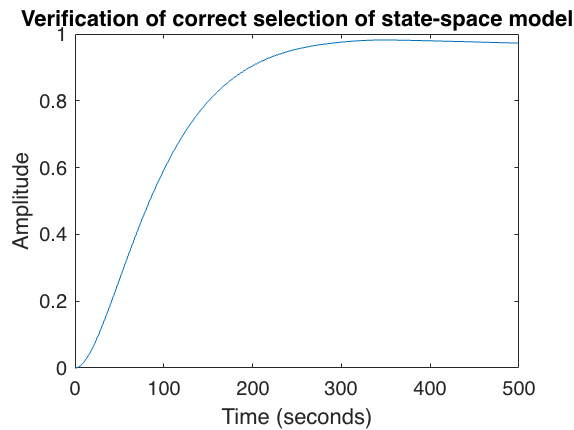

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end